filename = "Clear.xlsx";
clear = readtable(filename,'TextType','string'); 
head(clear)

ans = 8×3 table
    Var1    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                


filename = "Covid.xlsx";
covid = readtable(filename,'TextType','string'); 
head(covid)

ans = 8×3 table
    Var1    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                


data=[clear;covid] %merge datasets

data = 3985×3 table
    Var1    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            



data.Var1=randsample(data.Var1,height(data)) % shuffle datasets

data = 3985×3 table
    Var1    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

data=sortrows(data,"Var1")

data = 3985×3 table
    Var1    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

data(:,'Var1') = []

data = 3985×2 table
    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

head(data)

ans = 8×2 table
    event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

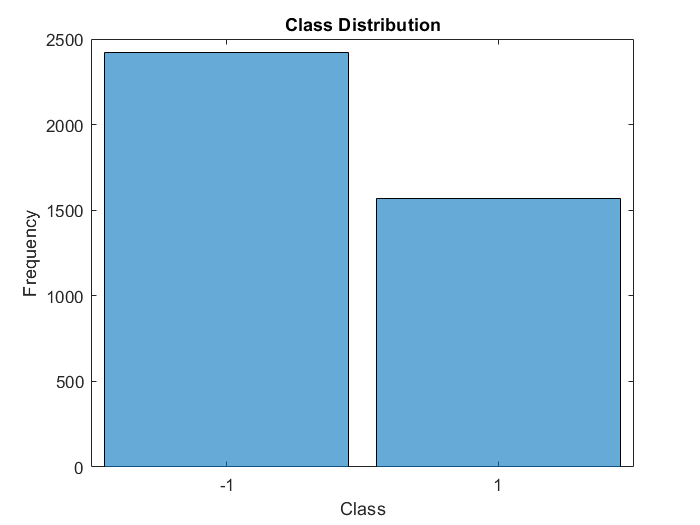


writetable(data,"covid_clear_dataset.csv") 

idx = strlength(data.description) == 0;
data(idx,:) = []; %remove rows with empty description

data.event_type = categorical(data.event_type); %convert the labels in the event_type column of the table to categorical
figure
h = histogram(data.event_type);%view labels distribution using a histogram
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")


cvp = cvpartition(data.event_type,'Holdout',0.1); %Partition the data into a training partition and a held-out test set
dataTrain = data(cvp.training,:);
dataTest = data(cvp.test,:);

%Extract the text data and labels from the tables.
textDataTrain = dataTrain.description;
textDataTest = dataTest.description;
YTrain = dataTrain.event_type;
YTest = dataTest.event_type;

documents = preprocessing(textDataTrain)

documents =   3587×1 tokenizedDocument:

     189 tokens: newcastle gloucester newcastle centre mathew tait answer critic score try make another stop gloucester grab draw falcon down break tait recently axe england just six nation outing inspire side lead lastgasp touchdown luke narraway pull visitor level gloucester miss victory henry paul fluff conversion seti kiole deny late try newcastle couple chance start second half lineouts corner fail make count joe shaw find dave walder release mark mayerholfer own former black broke clear pop ball tait halfway chip ahead michael stephenson scorch try walder convert give newcastle lifeline grab hand mayerhofler break tait make brilliant early run cut inside race score walder convert make just wide penalty minute mayerhofler scythe middle try hall charlton pop ball walders conversion take newcastle ahead three minute normal time leave narraway drive try corner level scor


bag = bagOfWords(documents)

bag =   bagOfWords with properties:

          Counts: [3587×38633 double]
      Vocabulary: [1×38633 string]
        NumWords: 38633
    NumDocuments: 3587



bag = removeInfrequentWords(bag,2); %Remove words from the bag-of-words model that do not appear more than two times
[bag,idx] = removeEmptyDocuments(bag);
YTrain(idx) = [];
bag

bag =   bagOfWords with properties:

          Counts: [3587×18365 double]
      Vocabulary: [1×18365 string]
        NumWords: 18365
    NumDocuments: 3587



%Train a supervised classification model using the word frequency counts from the bag-of-words model and the labels.
XTrain = bag.Counts;
mdl = fitcecoc(XTrain,YTrain,'Learners','linear')

mdl =   classreg.learning.classif.CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [-1    1]
    ScoreTransform: 'none'
    BinaryLearners: {[1×1 ClassificationLinear]}
      CodingMatrix: [2×1 double]


  Properties, Methods



%Predict the labels of the test data using the trained model and calculate the classification accuracy.
documentsTest = preprocessing(textDataTest);
XTest = encode(bag,documentsTest);

YPred = predict(mdl,XTest);
acc = sum(YPred == YTest)/numel(YTest)

acc = 1


str = [ ...
    "A large tree is downed and blocking traffic outside Apple Hill."
    "Damage to many car windshields in parking lot."
    "Lots of water damage to computer equipment inside the office."];
documentsNew = preprocessing(str);
XNew = encode(bag,documentsNew);
labelsNew = predict(mdl,XNew)

labelsNew = 3×1 categorical array
     -1 
     -1 
     -1 


function documents = preprocessing(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);



% Remove a list of stop words then lemmatize the words. To improve
% lemmatization, first use addPartOfSpeechDetails.
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove words with 2 or fewer characters, and words with 15 or more
% characters.
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);

end